# **Exercise 8 ECE537 **

# **Julie Jiang V00902597**

# **Zixuan Deng V00971633**

**1. Load the Exercise 8 data set into matlab. This data comprises a set of 100 time domain data records each comprised of approximately 10,000 samples. This data is noisy, contains measurement discontinuities and spurious data samples. Additionally, each time domain record contains the event denote by the variable event somewhere within each data record.**

load 'Exercise_8_data.mat';
whos;

  Name                                Size                  Bytes  Class      Attributes

  a                                   1x10000               80000  double               
  ans                                 1x10000               80000  double               
  approx                              1x81                    648  double               
  c                                   1x10018               80144  double               
  cd1                                 1x5001                40008  double               
  cd2                                 1x2502                20016  double               
  cd3                                 1x1252                10016  double               
  clean_data                          1x99               15860720  struct               
  coarsely_quantized                  0x0                       0  double               
  con_data                            1x10199               81592  double               
  con_data_1        

data 

data = 1×100 struct array with fields:
    x
    time


event

event =     0.1564    0.3090    0.4540    0.5878    0.7071    0.8090    0.8910    0.9511    0.9877    1.0000    0.9877    0.9511    0.8910    0.8090    0.7071    0.5878    0.4540    0.3090    0.1564    0.0000   -0.1564   -0.3090   -0.4540   -0.5878   -0.7071   -0.8090   -0.8910   -0.9511   -0.9877   -1.0000   -0.9877   -0.9511   -0.8910   -0.8090   -0.7071   -0.5878   -0.4540   -0.3090   -0.1564   -0.0000    0.1564    0.3090    0.4540    0.5878    0.7071    0.8090    0.8910    0.9511    0.9877    1.0000


**2. Apply statistical goodness-of-fit testing to formally determine whether or not the data can be modeled as having arisen from a stationary and/or ergodic processes across any reasonable time scales.**

% KS test for goodness-of-fit
index_1 = round(length(data(1).x) * 0.1)

index_1 = 1000

index_2 = length(data(1).x)

index_2 = 10001


test_result = [];

for i = 1:100
    y1 = data(i).x(1: index_1);
    y2 = data(i).x(index_1+1: index_1*2);
    y3 = data(i).x(index_1*2+1: index_1*3);
    y4 = data(i).x(index_1*3+1: index_1*4);
    y5 = data(i).x(index_1*4+1: index_1*5);
    y6 = data(i).x(index_1*5+1: index_1*6);
    y7 = data(i).x(index_1*6+1: index_1*7);
    y8 = data(i).x(index_1*7+1: index_1*8);
    y9 = data(i).x(index_1*8+1: index_1*9);
    y10 = data(i).x(index_1*9+1: index_2);
    
    result1 = kstest(y1);
    result2 = kstest(y2);
    result3 = kstest(y3);
    result4 = kstest(y4);
    result5 = kstest(y5);
    result5 = kstest(y5);
    result6 = kstest(y6);
    result7 = kstest(y7);
    result8 = kstest(y8);
    result9 = kstest(y9);
    result10 = kstest(y10);
    
    result = result1==result2 && result2==result3 && result3 == result4 &&result4 == result5 &&result5 == result6  && result6 == result7  &&result7 == result8  &&result8 == result9  &&result9 == result10;
    test_result = [test_result; result];
    
end

test_result

test_result =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


stationary_index = find(test_result == 1);
not_stationary_index = find(test_result == 0);
stationary_number = length(stationary_index)

stationary_number = 100

not_stationary_number = length(not_stationary_index)

not_stationary_number = 0

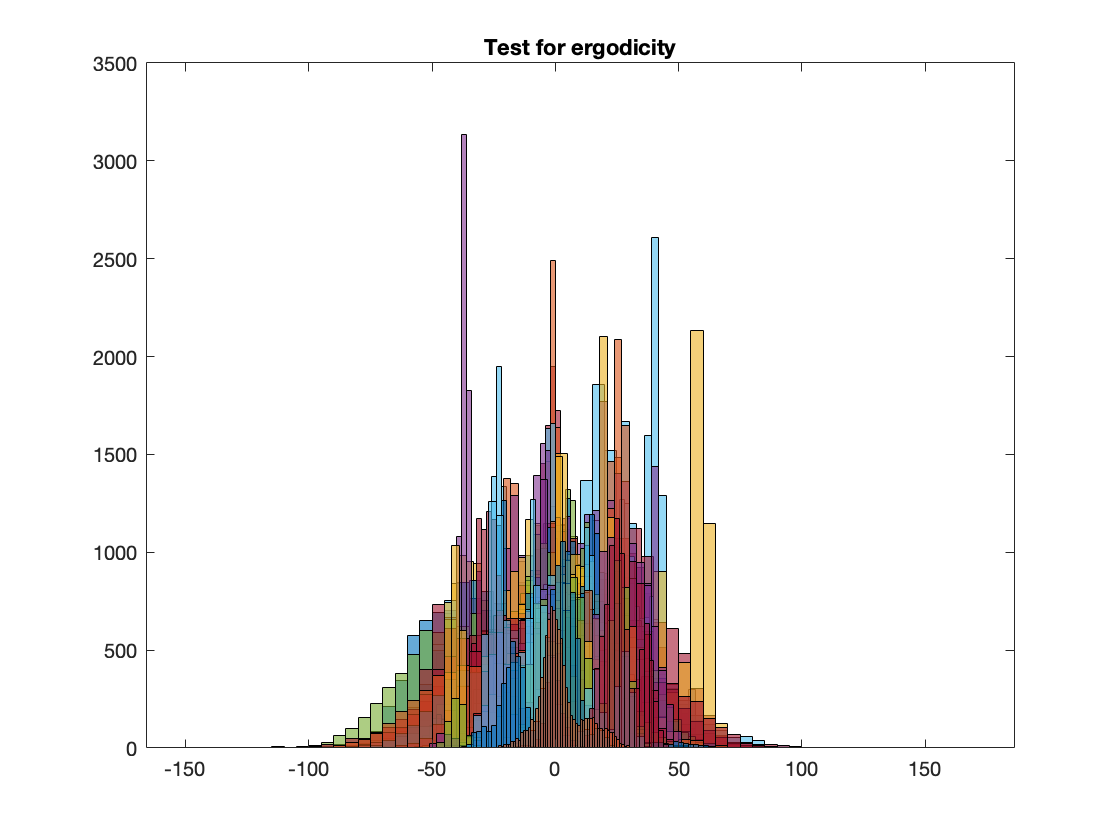

figure();

for i = 1 : 100
    
    data_hist = data(i).x;
    histogram(data_hist); 
    hold on;
    
end

title('Test for ergodicity');
hold off;

**Stationary: **

A stationary processes has statistical similarly hold for all moments in any time scales. To test stationary, we need to do KS-test stationarity testing along with the given windows [1].  

We have choosed 10% of dataset as one window, and the result of all KS-testing indicate that 100 windows sample are in steady-state PDF, that they are stationary. 

**Ergodicity: **

Ergodicity means that different experiments follow samestatistical distribution. 

Through different experiments' plot of distograms, we find the disrtibution of each experiment is quite similiar. For those centered in the middle and are symmetric, they are ergodic. 

**Reference: **

[1] Arora, D., Millman, E., & Neville, S. W. (2011). On the statistical behaviors of network-level features within manets. *2011 IEEE 22nd International Symposium on Personal, Indoor and Mobile Radio Communications*. https://doi.org/10.1109/pimrc.2011.6139677 

**3. Determine whether the data comprises constant sampling intervals or stochastic sampling intervals. Discuss the data analysis differences and distinctions that arise for these two cases. **

**• In the case of stochastic sampling develop and apply an appropriate methodology to enable correct data analysis and discuss why not correcting for the stochastic sampling is problematic. Would it be problematic in all cases? **

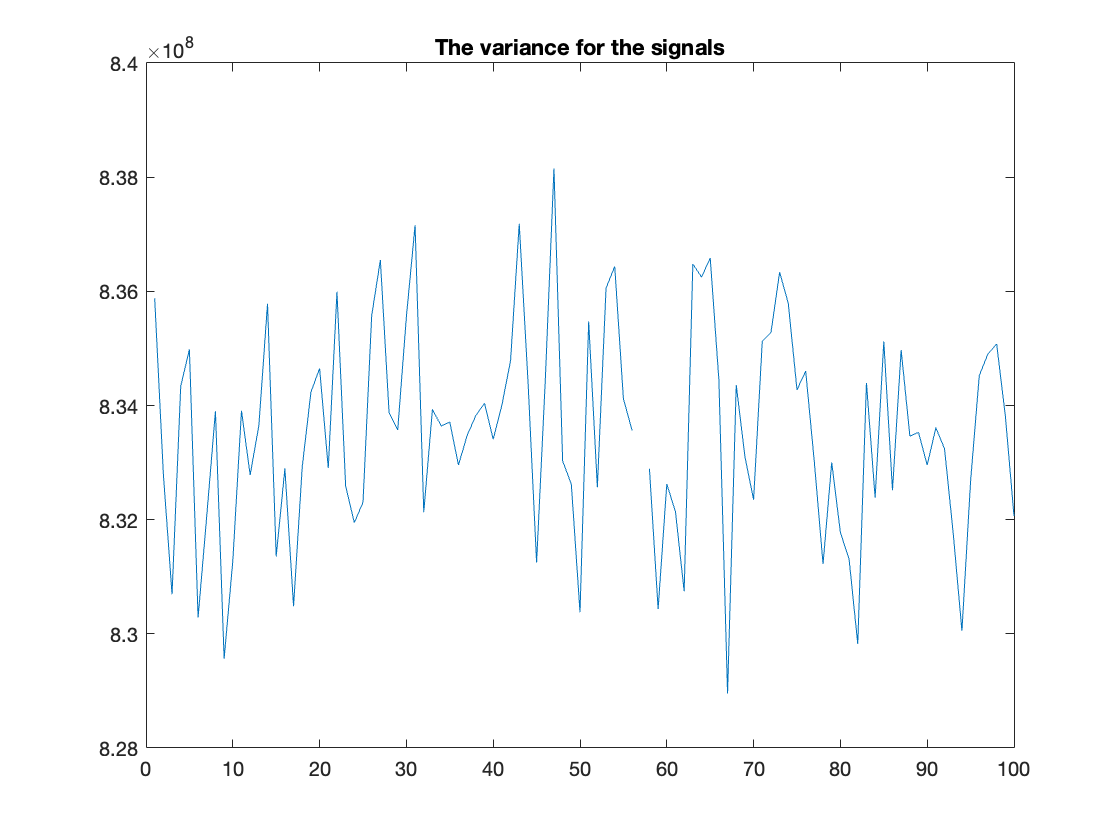

figure();
var_list = [];

for i = 1 : 100
    y = data(i).time;
    var_list = [var_list; var(y)];
end

% Plot variance
plot(var_list)
title('The variance for the signals');

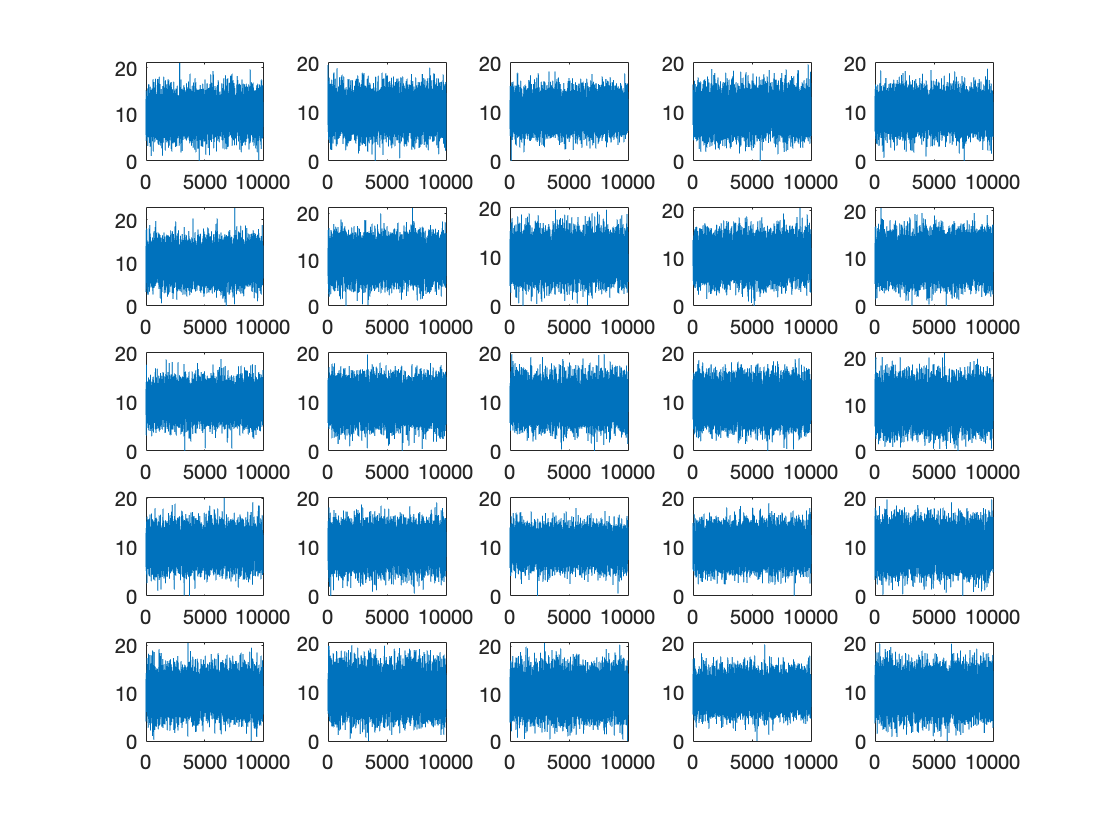


% Plot difference in time window width
figure();
for i = 1:25
    subplot(5, 5, i);
    plot(diff(data(i).time))
        
end
hold off

% Correct data
temp_data = data;

for i = 1:100
    equal_index = find(diff(data(i).time) == 0);
    
    if isempty(equal_index) ~= 1
        temp_data(i).time(equal_index) = [];
        temp_data(i).x(equal_index) = [];
    end
    
    
end


temp_data.time

ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0015    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0032    0.0033    0.0034    0.0035    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0047    0.0048    0.0049    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0002    0.0003    0.0005    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0027    0.0029    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0036    0.0037    0.0039    0.0039    0.0040    0.0041    0.0042    0.0043    0.0045    0.0046    0.0047    0.0047


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0017    0.0018    0.0018    0.0019    0.0021    0.0021    0.0022    0.0023    0.0024    0.0024    0.0026    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0044    0.0046    0.0046


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0031    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0032    0.0033    0.0034    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0029    0.0030    0.0032    0.0033    0.0034    0.0036    0.0037    0.0039    0.0040    0.0040    0.0041    0.0042    0.0043    0.0045    0.0045    0.0046    0.0047    0.0048    0.0049    0.0051    0.0052


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0014    0.0015    0.0016    0.0017    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0026    0.0027    0.0028    0.0029    0.0029    0.0030    0.0032    0.0033    0.0034    0.0035    0.0037    0.0038    0.0039    0.0040    0.0041    0.0041    0.0042    0.0043    0.0043    0.0045    0.0046    0.0046    0.0047


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0010    0.0010    0.0011    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0019    0.0020    0.0022    0.0023    0.0024    0.0025    0.0025    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0008    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0023    0.0025    0.0025    0.0026    0.0028    0.0029    0.0030    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0037    0.0038    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0045    0.0047    0.0047    0.0049


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0006    0.0006    0.0007    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0042    0.0043    0.0044    0.0045    0.0047    0.0048    0.0049    0.0050    0.0051


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0018    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0037    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0044    0.0044    0.0045    0.0046    0.0047


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0005    0.0006    0.0007    0.0009    0.0010    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0026    0.0028    0.0029    0.0030    0.0031    0.0031    0.0032    0.0033    0.0034    0.0035    0.0035    0.0036    0.0037    0.0037    0.0039    0.0040    0.0041    0.0042    0.0044    0.0045    0.0046    0.0047    0.0049


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0033    0.0035    0.0036    0.0036    0.0037    0.0038    0.0039    0.0040    0.0040    0.0041    0.0042    0.0043    0.0043    0.0044    0.0045    0.0047    0.0048    0.0048    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0012    0.0012    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0032    0.0033    0.0034    0.0034    0.0036    0.0037    0.0038    0.0040    0.0040    0.0041    0.0042    0.0043    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0014    0.0016    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0029    0.0029    0.0030    0.0032    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0038    0.0039    0.0040    0.0042    0.0042    0.0044    0.0044    0.0046    0.0047    0.0048


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0008    0.0008    0.0009    0.0011    0.0011    0.0012    0.0014    0.0015    0.0015    0.0017    0.0018    0.0019    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0007    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0029    0.0029    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0039    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0003    0.0003    0.0005    0.0005    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0032    0.0032    0.0034    0.0035    0.0035    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050


ans = 	1.0e+05 *

         0    0.0002    0.0003    0.0004    0.0004    0.0005    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0019    0.0020    0.0021    0.0022    0.0024    0.0025    0.0027    0.0027    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0038    0.0039    0.0040    0.0041    0.0042    0.0042    0.0043    0.0044    0.0046    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052    0.0053


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0007    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0017    0.0019    0.0019    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0034    0.0035    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0020    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0030    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0039    0.0039    0.0041    0.0042    0.0044    0.0044    0.0046    0.0046    0.0047    0.0048    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0019    0.0019    0.0021    0.0022    0.0023    0.0023    0.0024    0.0026    0.0026    0.0027    0.0028    0.0029    0.0029    0.0031    0.0032    0.0032    0.0033    0.0033    0.0034    0.0035    0.0036    0.0038    0.0039    0.0040    0.0040    0.0042    0.0043    0.0045    0.0046    0.0047    0.0047    0.0048


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0017    0.0018    0.0019    0.0020    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0037    0.0038    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0047    0.0048    0.0049    0.0051    0.0051


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0021    0.0022    0.0023    0.0023    0.0024    0.0025    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0034    0.0036    0.0036    0.0037    0.0038    0.0039    0.0039    0.0040    0.0041    0.0042    0.0043    0.0043    0.0045    0.0045    0.0047


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0008    0.0008    0.0010    0.0010    0.0011    0.0011    0.0012    0.0014    0.0015    0.0016    0.0017    0.0018    0.0018    0.0020    0.0020    0.0021    0.0022    0.0023    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0032    0.0033    0.0034    0.0035    0.0035    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0039    0.0040    0.0041    0.0042    0.0044    0.0044    0.0045    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0011    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0019    0.0020    0.0021    0.0022    0.0023    0.0023    0.0024    0.0025    0.0026    0.0027    0.0029    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0036    0.0037    0.0038    0.0039    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0046    0.0046    0.0047    0.0048    0.0049


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0009    0.0009    0.0010    0.0012    0.0012    0.0013    0.0015    0.0016    0.0017    0.0017    0.0019    0.0020    0.0021    0.0021    0.0023    0.0024    0.0024    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0011    0.0012    0.0013    0.0015    0.0015    0.0017    0.0018    0.0018    0.0020    0.0020    0.0021    0.0023    0.0023    0.0025    0.0025    0.0027    0.0028    0.0029    0.0030    0.0030    0.0031    0.0032    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0008    0.0009    0.0011    0.0012    0.0013    0.0014    0.0016    0.0017    0.0018    0.0019    0.0019    0.0021    0.0022    0.0024    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0033    0.0035    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0012    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0027    0.0028    0.0029    0.0030    0.0030    0.0032    0.0032    0.0033    0.0034    0.0035    0.0036    0.0036    0.0037    0.0038    0.0040    0.0041    0.0042    0.0043    0.0043    0.0045    0.0046    0.0046    0.0048    0.0049    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0028    0.0028    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0044    0.0044    0.0045    0.0046    0.0047    0.0049    0.0049    0.0050    0.0051


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0028    0.0030    0.0031    0.0032    0.0033    0.0034    0.0036    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0048    0.0048    0.0050    0.0051


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0009    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0016    0.0016    0.0017    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0027    0.0028    0.0029    0.0030    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0043    0.0044    0.0045    0.0046    0.0047    0.0047    0.0048


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0009    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0019    0.0019    0.0021    0.0022    0.0023    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0030    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0004    0.0005    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0013    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0021    0.0023    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0036    0.0037    0.0038    0.0039    0.0041    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048


ans = 	1.0e+05 *

         0    0.0001    0.0001    0.0002    0.0003    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0012    0.0012    0.0014    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0032    0.0033    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0008    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0020    0.0020    0.0021    0.0023    0.0024    0.0025    0.0026    0.0028    0.0028    0.0030    0.0031    0.0032    0.0032    0.0034    0.0035    0.0036    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0045    0.0046    0.0047    0.0047    0.0048    0.0049    0.0050    0.0051


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0019    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0028    0.0029    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0047


ans = 	1.0e+05 *

         0    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0017    0.0018    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0030    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0046    0.0047    0.0048


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0017    0.0018    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0016    0.0017    0.0019    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0027    0.0028    0.0029    0.0030    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0028    0.0030    0.0030    0.0032    0.0032    0.0033    0.0034    0.0035    0.0036    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0048    0.0049    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0002    0.0003    0.0005    0.0005    0.0007    0.0008    0.0009    0.0009    0.0010    0.0011    0.0012    0.0013    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0023    0.0023    0.0024    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0034    0.0035    0.0036    0.0036    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0050


ans = 	1.0e+05 *

         0    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0006    0.0007    0.0008    0.0009    0.0011    0.0011    0.0012    0.0013    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0022    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0035    0.0037    0.0038    0.0039    0.0040    0.0041    0.0041    0.0042    0.0043    0.0044    0.0044    0.0045    0.0046    0.0047    0.0048


ans = 	1.0e+05 *

         0    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0031    0.0032    0.0034    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047


ans = 1×10000
         0   15.6338   32.7760   49.5636   59.6982   67.1806   79.0866   89.7350   99.2136  113.6444  130.7802  141.5632  156.8444  166.0914  174.8333  185.1527  193.2424  201.9856  210.2346  223.3929  233.5029  244.1180  256.2801  262.4439  273.1657  284.7207  295.0138  303.4208  316.2854  327.2750


ans = 1×10000
         0   11.9854   20.4387   30.1243   40.6272   48.8814   60.8378   72.4707   79.9137   90.6042   99.8699  108.4686  115.9283  126.8810  137.4936  143.0918  155.5526  167.3943  175.5830  185.6335  193.3221  206.0364  216.1981  224.2914  233.1135  242.4818  253.1894  260.8471  271.5220  282.1184


ans = 1×10000
         0    5.4786   18.4074   26.7505   38.3815   47.6021   57.0305   69.4021   76.9228   90.1319   99.8319  107.9765  116.8937  127.2070  138.1092  145.9445  156.6406  162.3579  175.1975  183.9644  195.8962  207.4059  220.2872  233.9900  242.5346  252.2573  263.2635  271.9855  282.5041  298.0966


ans = 1×10000
         0    9.3707   21.4854   36.1515   46.9618   59.8900   68.8291   77.0175   82.4328   90.7000  105.0606  112.4811  122.9115  128.3699  142.5681  157.2923  169.0412  176.4232  182.1930  188.7082  203.6340  218.2798  222.8021  234.2577  242.6656  253.3307  264.2574  272.0267  281.1677  288.2144


ans = 1×10000
         0    8.2851   15.6756   26.9150   33.7769   46.3890   57.3867   71.8885   85.2249   98.3029  103.1434  110.8192  122.2107  126.8817  133.8149  143.3928  152.3458  162.5019  173.1550  177.7066  188.3883  203.8671  211.2057  216.4144  225.4264  238.8204  248.7867  257.7197  269.7435  283.0333


ans = 1×10000
         0    8.2257   13.7652   20.7515   27.8703   36.9379   44.7484   57.9476   65.5603   77.9780   86.8465   96.7237  103.6781  113.7046  123.5584  134.3479  141.3483  151.9639  161.9937  173.3016  180.4048  185.8352  197.9941  208.9301  218.4443  225.9923  238.6146  246.0029  252.7325  261.8371


ans = 1×10000
         0   13.2890   20.2050   25.4679   36.3701   46.8954   58.9393   72.1089   85.9227   94.5096  100.8366  110.7201  120.9692  129.3026  138.9398  152.8974  164.6730  171.6384  183.6757  197.1422  204.9300  213.2204  221.4861  232.2527  239.0324  248.3369  259.4512  266.7650  277.2409  282.7393


ans = 1×10000
         0    9.0107   18.8750   32.7925   46.1343   55.3918   64.1115   69.2537   77.2110   86.5520   96.3527  107.9933  119.8429  131.0206  139.8091  147.3563  155.9889  163.1451  174.2936  179.0614  189.8860  196.9919  210.1382  226.2860  244.7173  253.9489  267.5553  275.1447  285.0984  294.9187


ans = 1×10000
         0   11.0483   21.2936   32.9445   43.7317   51.3828   60.9299   73.5969   86.2421  100.0102  111.9809  122.5731  134.9843  143.4173  151.9684  160.3759  170.7041  183.0511  194.8633  207.9840  214.6077  223.0814  235.0729  248.3035  258.3159  268.3527  281.0027  289.5781  298.2461  307.9832


ans = 1×10001
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


ans = 1×10000
         0   11.5505   22.5553   31.1552   41.7591   50.6404   60.6583   69.7106   80.1312   90.5536  103.6143  114.0627  122.8325  131.9504  137.6730  146.9260  152.5303  161.4605  175.0595  187.5243  196.1909  208.2041  217.9708  226.3442  237.4096  244.9290  252.5284  261.2742  270.3690  277.8893


ans = 1×10000
         0    8.7377   24.3552   33.3078   46.8196   59.0900   64.3309   75.5405   90.8992   97.8740  109.0171  116.3016  125.9073  132.3994  141.1971  144.7484  151.8169  167.8832  178.3798  190.9994  200.1315  213.3101  226.5556  231.6964  241.0267  248.6635  256.2831  264.8935  276.7318  283.9551


ans = 1×10000
         0    9.1376   18.3576   27.7473   43.8921   56.0236   68.0744   78.9423   89.3762  105.3691  118.2671  130.6982  142.0570  150.8076  162.0199  173.8013  181.7144  194.5637  203.3096  209.1401  216.5235  229.2716  238.8132  249.7632  257.3773  270.0351  279.9063  289.5104  301.3861  311.2334


ans = 1×10000
         0    6.5132   16.2140   23.8065   36.7934   46.1799   57.0244   67.2233   77.3009   83.9814   94.9112  106.3671  116.6025  129.1318  136.7900  145.3027  150.9241  156.6842  168.3676  173.6727  184.5691  192.2935  205.6867  215.8858  225.3156  235.1479  241.9560  252.0970  264.4193  276.1771


ans = 1×10000
         0    6.9587   18.3343   28.8110   37.2149   42.4434   54.1769   64.4622   76.6190   87.6737  101.5044  109.1925  120.1338  127.6132  135.6934  147.1476  155.6305  165.9700  174.8289  186.5230  194.3790  203.9309  213.4519  220.7605  229.2630  242.1266  254.5034  262.9531  272.4098  285.0074


ans = 1×10000
         0    8.0597   17.0111   20.3566   30.4151   41.6351   49.8992   58.1480   66.0900   76.5884   89.9739   96.8359  108.1629  123.1886  135.5090  143.3343  152.7450  162.2897  173.9139  178.6610  190.0048  198.6274  208.6869  218.3168  232.1631  241.0357  253.3422  267.8879  278.4296  288.8461


ans = 1×10000
         0   10.5704   19.7200   28.0941   35.1614   44.5391   55.3202   67.1364   82.2127   87.3368   94.3058  105.7269  115.1933  123.7390  132.1411  144.3966  152.8336  164.6306  174.8740  184.1862  196.0310  206.7713  220.0348  229.5034  237.4681  246.0930  251.4053  263.3800  272.0449  282.3793


ans = 1×10000
         0   12.4891   19.8126   32.4381   37.7231   48.8308   61.4636   74.4336   80.2358   91.3302   99.9019  111.5054  122.7164  127.9859  136.5629  147.7631  158.3265  168.3268  174.8707  185.2270  198.2383  208.1411  221.7617  223.6681  234.1998  242.1990  253.5413  262.8467  268.3660  280.5832


ans = 1×10000
         0    8.1410   19.2509   25.7679   33.8701   43.6985   52.6258   61.3244   70.9401   80.4823   90.4228  103.9824  114.3101  126.0421  135.7645  148.2931  156.7404  165.5360  178.4357  197.0928  209.0088  218.7191  232.0332  238.8851  250.4092  263.8883  274.1407  285.6140  297.0201  305.6054


ans = 1×10000
         0   10.3984   11.5426   21.9406   31.7556   43.9535   52.3082   65.2931   74.8369   86.7080   99.3708  114.3756  127.8207  141.6278  153.9580  166.7098  175.8917  182.9150  194.6618  200.2270  207.1114  218.7020  226.2548  231.4382  240.8051  250.1915  259.7680  274.0513  287.1204  293.6766


ans = 1×10000
         0   13.9339   24.9472   37.2602   52.2837   58.6720   68.1616   77.1513   93.3107  102.3239  113.6314  123.5786  132.0796  138.8284  148.6285  157.5605  172.5193  182.2622  190.4601  196.7416  210.9769  222.7471  233.0587  243.1079  254.2769  266.0061  272.7991  283.3375  298.0556  310.0925


ans = 1×10000
         0   10.2057   21.4597   30.4468   37.2457   50.0809   56.1425   65.6319   77.6389   91.0219   99.6867  105.0858  111.9804  121.8288  126.9648  139.3420  149.7399  159.1905  170.8658  182.7598  193.3221  205.6683  217.4070  227.7132  240.5298  254.8262  264.2070  279.0240  286.6003  297.8868


ans = 1×10000
         0    7.0688   13.3809   23.1752   35.2487   45.1348   60.4569   71.6711   84.3530   92.1500  104.1285  116.0557  123.7619  137.8999  142.9438  153.8197  160.4860  168.5593  175.1116  183.4652  189.5014  200.1559  211.7590  223.3409  230.8412  239.4277  249.1679  258.5423  267.8916  275.6593


ans = 1×10000
         0   11.9578   22.0302   35.1892   47.4442   53.5251   62.3167   70.7772   82.8066   94.1176  102.4357  114.9060  127.0554  135.4718  146.5068  154.4886  162.6779  175.7357  185.9716  199.7961  206.3758  212.0164  221.8705  230.3982  243.6094  257.1565  270.8493  276.0847  286.6726  298.1357


ans = 1×10000
         0    7.1595   18.3609   33.4341   40.2766   48.1363   57.9952   69.8649   76.9003   88.7272   95.7544  108.0757  114.6244  121.3995  135.5462  143.3779  153.5805  159.5528  172.4849  182.6994  193.3592  206.0417  220.7029  232.1861  240.3842  248.2393  258.3136  271.3217  276.4722  285.9449


ans = 1×10000
         0   16.1993   24.1041   34.6235   46.6861   58.0725   71.6154   80.9366   95.6003  104.5037  114.8300  121.5908  129.4191  145.2888  155.6515  159.6253  168.7728  180.7600  192.4242  204.0540  208.4193  215.2178  225.2645  234.0510  239.8006  252.6544  261.7434  265.7555  272.5457  282.1202


ans = 1×10000
         0    8.1268   14.6839   21.0334   33.6762   44.6789   55.8236   62.8657   71.9824   84.3629   95.9523  102.3210  111.6097  121.0795  128.2002  137.5836  144.8120  156.2390  166.4728  174.1998  186.1249  191.4509  205.8708  214.8668  221.1392  231.4390  239.5745  248.1749  259.7444  274.6764


ans = 1×10000
         0    8.0390   19.5271   31.9408   35.9043   48.3296   62.3039   73.7296   81.3919   96.4492  112.3315  119.5505  130.4522  138.9411  148.4238  156.4372  167.6849  175.7828  185.9896  195.3482  204.1324  213.7109  223.9328  237.2740  245.8560  257.0226  262.7321  271.4287  280.0751  286.4856


ans = 1×10000
         0   10.6526   19.6293   30.3128   43.3359   55.0774   64.3470   73.8009   84.3462   89.7709   98.2511  104.1149  113.6640  125.5445  140.5480  153.7610  164.0726  172.3060  184.0000  194.7002  207.4317  222.4930  240.1610  250.2020  258.4237  273.9063  284.9869  299.1310  302.4760  308.2195


ans = 1×10000
         0   12.7786   22.8353   33.0498   45.2084   56.0579   63.5088   71.8349   81.6160   94.1585  102.0806  108.7831  121.0007  127.6009  142.5565  153.6194  163.1487  174.9540  182.7697  194.8745  204.0667  216.2061  228.1729  234.4944  241.0954  247.4239  257.4186  265.8933  277.5264  287.8326


ans = 1×10000
         0   11.1837   18.0371   25.2554   37.6823   46.4311   57.3233   69.4051   81.3168   91.2033  104.1886  111.7483  121.8551  130.0072  138.4857  149.9633  157.7905  168.3237  176.3787  188.4896  198.0782  206.2407  219.9456  232.5253  243.2598  256.5427  260.8304  269.1089  279.8197  288.0018


ans = 1×10000
         0   14.2542   23.3944   33.5597   43.9188   52.5737   63.5912   76.6448   83.8756   95.3046  105.2653  118.7336  127.0562  132.0846  140.9695  151.9027  161.0084  173.7202  182.5409  188.3728  203.3999  212.9037  223.1038  229.6878  247.5387  253.6380  263.6701  276.5008  293.4501  302.0294


ans = 1×10000
         0    9.4299   17.8642   29.0221   36.7233   47.5116   55.7435   62.2341   69.3635   77.9962   87.6253   95.0623  101.4419  108.7835  118.3651  130.8537  139.6152  152.2059  165.4575  170.6995  178.0469  189.6178  198.2573  210.2002  223.9434  226.3643  237.9983  248.8358  260.1200  271.0446


ans = 1×10000
         0    9.8242   22.1541   29.1259   37.6561   47.6275   55.0405   61.6306   72.4194   83.3449   95.2018  104.9141  116.4813  126.2349  137.3385  147.8634  159.1108  169.8139  184.2895  194.1134  205.3412  218.1021  228.2872  240.0440  252.0220  261.9407  273.6908  277.9481  287.4416  296.8301


ans = 1×10000
         0   12.3669   21.4021   27.2229   35.1081   45.7532   54.8108   61.8413   72.1211   81.7397   91.4665  102.3749  113.9137  126.8929  136.5778  144.7746  157.2632  169.1705  185.7767  191.2173  200.1282  213.5537  221.6582  229.4655  237.3645  251.6386  259.4175  272.7290  284.2497  290.9150


ans = 1×10000
         0    8.3609   19.2092   30.6857   44.9553   50.8745   57.5855   67.9629   73.0262   87.9997   98.7412  105.6828  117.8233  126.7765  139.5086  153.7201  162.9827  171.6595  180.4036  193.3536  198.8291  212.5094  223.0315  235.6025  243.0930  254.9437  265.9433  275.5506  285.7875  296.8169


ans = 1×10000
         0    8.5820   18.2558   29.9621   36.0041   47.8255   60.2941   70.2499   79.6662   88.8829   95.3981  107.0862  118.7311  129.1565  135.0160  147.8052  154.4341  162.7561  170.4009  176.3868  186.7364  196.5490  207.2522  215.8636  225.7343  238.7672  249.3722  257.6871  263.2277  275.8955


ans = 1×10000
         0    9.2309   23.5798   34.0723   46.5899   57.4278   69.6784   83.5015   97.7922  109.7628  118.0116  128.7566  138.7795  148.8644  155.6828  167.3586  179.1998  189.7865  200.9432  213.7236  225.1677  229.6004  241.4164  251.7130  265.1908  277.8779  287.6038  296.2351  308.0177  317.8370


ans = 1×10000
         0   11.9141   20.7166   28.3492   33.7972   45.3165   57.0016   66.6398   75.9376   85.7715   95.5227  108.3303  119.6664  127.6152  138.8959  154.0584  163.9684  176.6026  187.9289  193.9738  203.8435  216.5596  227.1281  234.6398  246.0208  251.3411  263.6605  272.2151  282.7621  294.4300


ans = 1×10000
         0    8.9556   17.3238   32.1210   43.5637   55.0513   65.7511   74.1193   81.2451   91.4999  102.3444  114.5573  124.0447  131.2755  139.6644  147.3172  158.9122  171.3222  180.9005  189.4458  198.3023  204.2610  219.9738  229.6870  237.0331  252.2919  260.9148  269.0934  278.6117  282.1972


ans = 1×10000
         0    9.1593   18.0937   32.7061   36.8148   44.1227   55.8033   63.7910   72.3744   82.8572   92.0688   99.8588  109.4186  121.6570  131.2341  137.7015  145.5893  159.0145  168.7264  175.3295  184.0304  193.1073  202.3784  212.4652  220.3597  237.4777  250.4413  262.9155  271.1133  281.6000


ans = 1×10000
         0   10.9342   21.9992   33.5325   49.2309   58.7474   71.4187   83.2613   97.0125  105.6012  112.5178  120.4260  130.3868  140.7531  149.7127  160.9768  167.2342  176.9974  183.4811  191.0153  199.1858  212.3403  220.3084  228.7702  234.9553  240.3959  247.9058  257.0457  265.5296  275.3685


ans = 1×10000
         0    7.9969   19.7410   31.3270   45.3793   57.9761   68.7676   75.1958   84.5434   89.8577  100.7394  112.2681  124.8325  134.4648  146.7101  158.5259  168.6374  176.7210  184.8238  195.0074  203.8814  212.1461  223.6542  234.0845  245.0102  249.4853  260.7019  267.4644  280.6415  285.8537


ans = 1×10000
         0   10.5324   22.1182   30.8172   41.1345   51.0789   61.3330   73.4457   80.0567   89.7157   97.9170  109.2114  118.7509  131.6091  140.2864  150.3883  159.3800  164.1829  177.9789  189.1093  204.8079  214.2196  226.1598  233.9327  241.0657  249.7916  259.5450  270.0839  280.4437  291.6969


ans = 1×10000
         0   16.7135   28.1564   35.7883   46.1930   57.6388   66.1142   75.8276   83.1618   92.7667  103.7386  119.3457  131.2923  143.0018  159.4082  162.6786  172.9460  179.4466  185.1217  199.2743  208.2435  219.3395  233.3692  243.6002  250.5415  261.6385  267.7355  278.7791  289.2667  300.4687


ans = 1×10000
         0   11.4655   27.3858   37.3769   48.3142   60.1318   71.2440   85.0797   97.4966  103.6740  109.7186  119.4402  130.7962  135.6009  141.7890  155.9151  165.5196  173.3435  179.5728  184.5406  191.2397  199.9972  213.2451  224.4472  230.7799  239.6786  255.9932  264.8970  279.5115  289.7020


ans = 1×10000
         0   12.7999   25.4012   36.8373   47.3877   57.6688   73.6912   86.2893   93.7500   99.0198  104.5964  114.5434  126.9336  138.2782  153.6255  162.2271  172.7808  185.1365  196.4569  205.9694  214.5995  225.8144  233.8889  244.1660  254.7581  264.5149  275.0329  281.6308  288.1062  300.3263


ans = 1×10000
         0   10.1802   23.1705   36.4606   45.1086   52.6385   66.1757   75.1659   83.8443   93.6790  105.5829  113.9054  121.9492  136.1101  141.6759  153.2157  157.8990  167.8180  177.3787  188.9795  197.2232  206.6490  213.7303  225.6483  236.0907  249.4975  261.7372  273.7456  281.5915  293.3053


ans = 1×10000
         0   12.5731   20.4229   32.4429   44.1431   54.3069   66.8666   73.4875   83.1393   96.8348  102.4460  113.3384  123.5416  130.4748  135.3250  145.1481  152.1158  167.3782  178.7309  190.8943  201.6642  206.0608  217.8366  223.3109  238.0621  244.5470  254.7314  263.9368  275.5211  288.5882


ans = 1×10000
         0    8.1492   18.5713   32.3602   42.6632   54.5520   64.2953   74.3221   89.0761  100.5537  107.7064  113.1585  122.1965  129.9188  137.7671  149.1358  160.7047  166.8421  172.7495  184.8579  195.3307  200.2320  209.8907  220.8211  230.4843  237.1274  246.3268  259.9737  266.3774  273.9426


ans = 1×10000
         0   11.2510   21.5823   33.9821   48.3459   56.0303   68.7330   75.5209   82.7072   93.2102  102.9417  113.2227  129.5998  139.7919  148.7102  161.9934  174.5738  186.2485  193.0732  201.8072  213.7634  221.5566  232.2749  238.0556  247.5542  259.8734  265.8802  275.0861  282.0788  289.5347


ans = 1×10000
         0    9.5136   20.6631   24.9224   29.8931   41.1716   49.7270   58.7274   67.7250   74.2109   85.6663   95.4623  106.5541  119.3228  128.4715  140.2096  148.0046  154.7584  166.4890  180.0410  189.2893  197.5560  209.7112  217.9636  228.9028  238.2506  247.6594  254.0913  267.1830  283.3252


ans = 1×10000
         0   13.5776   23.1465   32.3463   42.7884   45.6573   56.4664   63.9408   70.4593   80.2771   92.9166  103.5392  113.5171  122.0901  131.4362  133.6955  145.4440  155.3988  167.8804  176.8060  186.6969  197.6259  208.6975  215.5746  222.3984  230.7493  242.9220  253.5209  264.6179  273.4314


%we found 57 is all NaN.
temp_data(57) = [];
clean_data = temp_data;


for i = 1:99    
    xx = linspace(min(temp_data(i).time), max(temp_data(i).time), 10000);
    y_corrected_data = spline(temp_data(i).time, temp_data(i).x, xx);
    clean_data(i).x = y_corrected_data;
    clean_data(i).time = xx;
end

% Plot difference in time window width after correction
sampling_interval_difference = round(diff(xx), 2)

sampling_interval_difference = 1×9999
    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


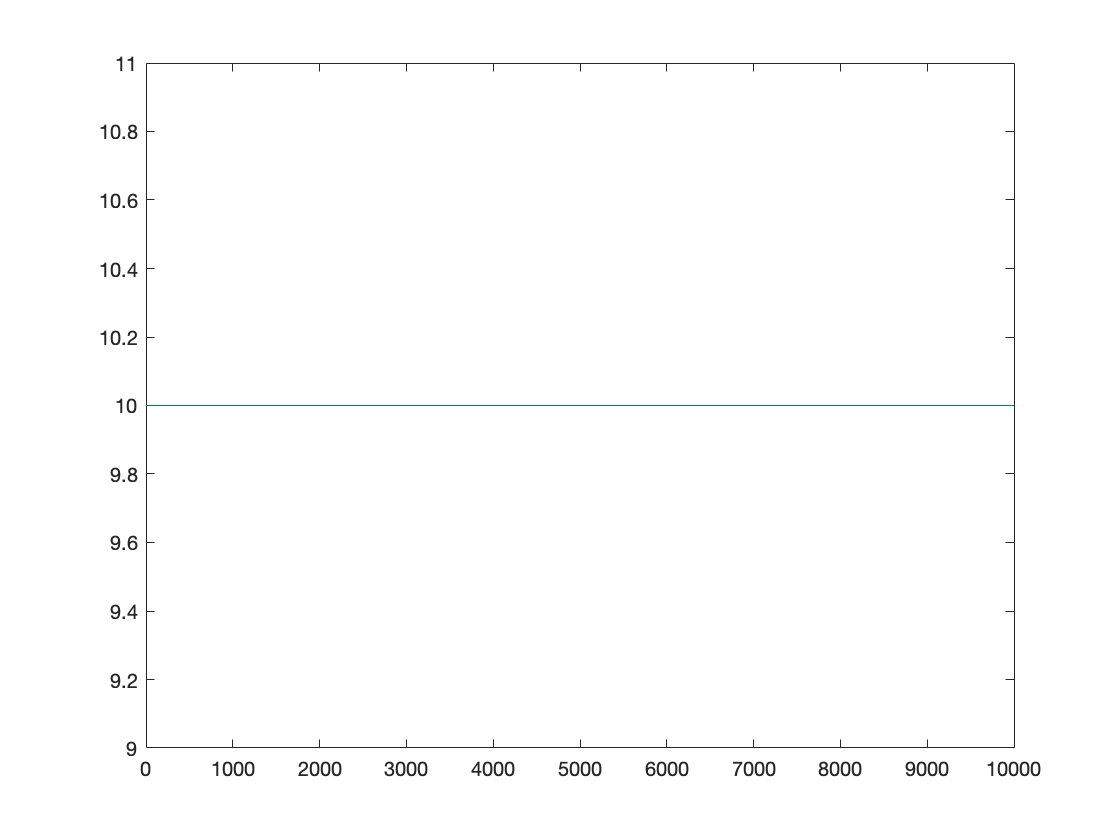

figure();
plot(sampling_interval_difference)

From those subplots, we could find the data comprise stochastic sampling intervals as the the time stamp interval changes, it's not constant. In many of the time series data used to train model assumed constant sampling intervals. And many filtering techniques cannot be used if the data comprise stochastic sampling intervals. And usually stochastic sampling is problematic. For example, if few time interval are use second as unit, and others use hours. This stochastic sampling intervals will bring trouble when train model. 

Stochastic sampling is not always problematic. Sometimes we only need to look at the value, and the time interval is not that important, then we do not need to correct the stochastic sampling intervals. 

To correct the stochastic sampling intervals, we apply Cubic spline data interpolation. After correct the sampling intervals, we see the result plot become a straight line. The sampling intervals become constant. 

**Ex8 Q4 Determine whether any of the data records contain coarsely quantized data and discuss the impacts and concerns that arise for coarsely quantized data sets. **

**How would you correct for coarsely quantized data and is it “correctable”? **


number = 2^6 % 6 means 6 bits

number = 64


for i = 1:100

    coarsely_quantized = find(length(unique(data(i).x)) < number);
    
end

num_coarsely_quantized = length(coarsely_quantized)

num_coarsely_quantized = 0

**Discussion: **

We know that if the data records are less than 64 [2], than they are coarsely quantized data sets. From the output, we find the data records do not contain any coarsely quantized data.

If the signal is coarsely quantized, we can denoise the data. The paper shows a practical wavelet-baed approach to denoising coarsely quantized signals [3].

**Reference: **

[2] Neville_StephenWilliam_PhD_1998_ch3

[3] S. Neville and N. Dimopoulos, "Wavelet denoising of coarsely quantized signals," in IEEE Transactions on Instrumentation and Measurement, vol. 55, no. 3, pp. 892-901, June 2006, doi: 10.1109/TIM.2006.873790.

**Q5. Apply median filtering to remove all spurious data samples. Discuss the assumption that median filtering makes.**

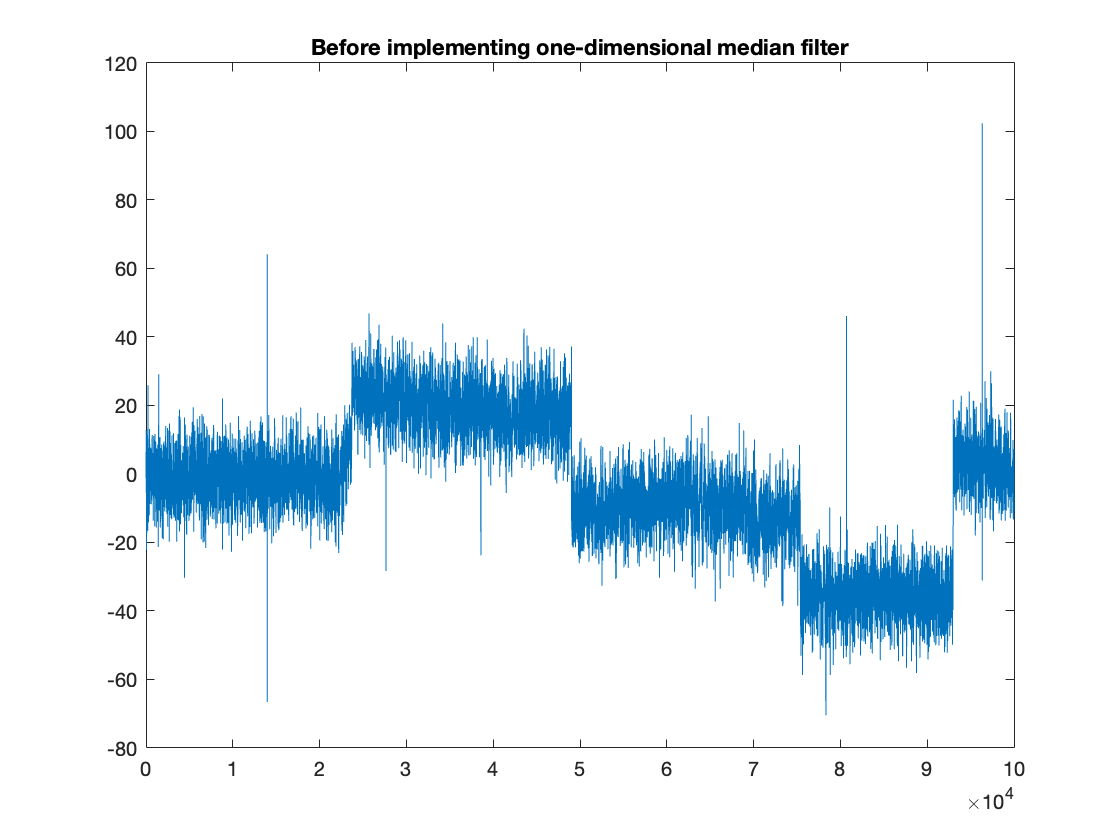

data_3_order = clean_data;
data_15_order = clean_data;
data_30_order = clean_data;

plot(data_3_order(1).time, data_3_order(1).x)
title('Before implementing one-dimensional median filter');

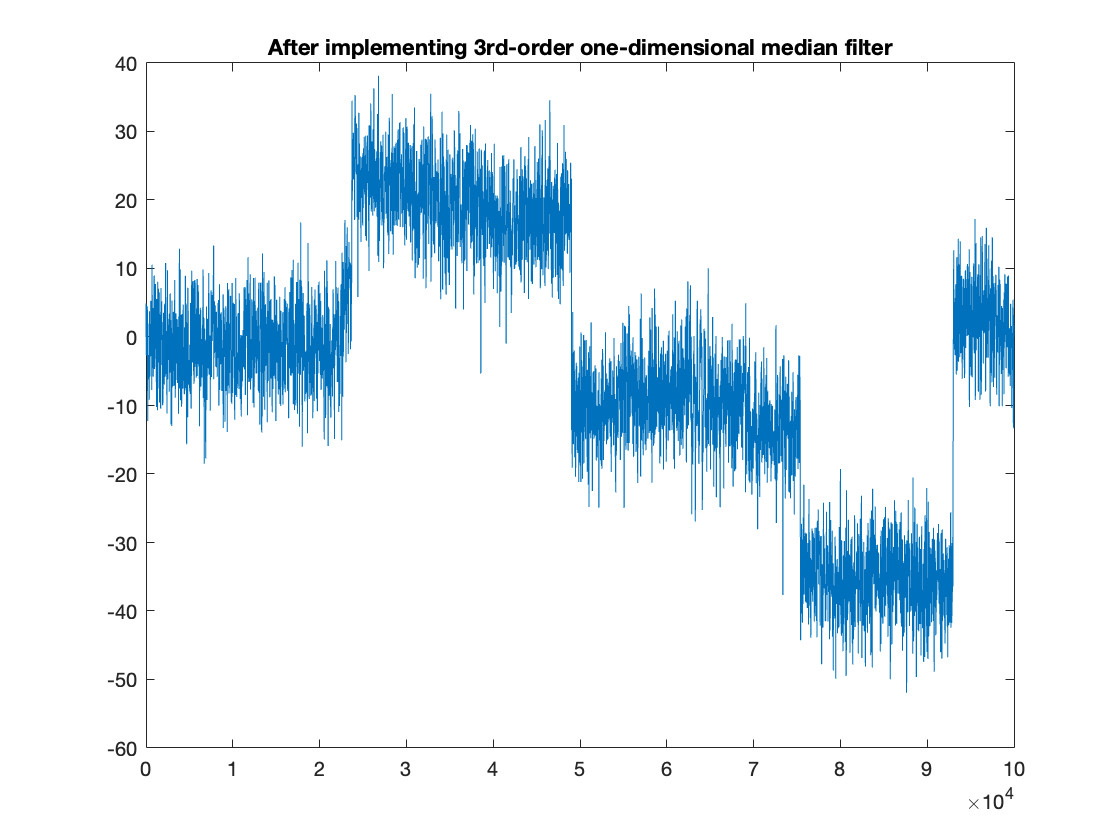


for i = 1:length(clean_data)
    data_3_order(i).x = medfilt1(clean_data(i).x);
    data_15_order(i).x = medfilt1(clean_data(i).x, 15);
    data_30_order(i).x = medfilt1(clean_data(i).x, 30);
end

plot(data_3_order(1).time, data_3_order(1).x)
title('After implementing 3rd-order one-dimensional median filter');

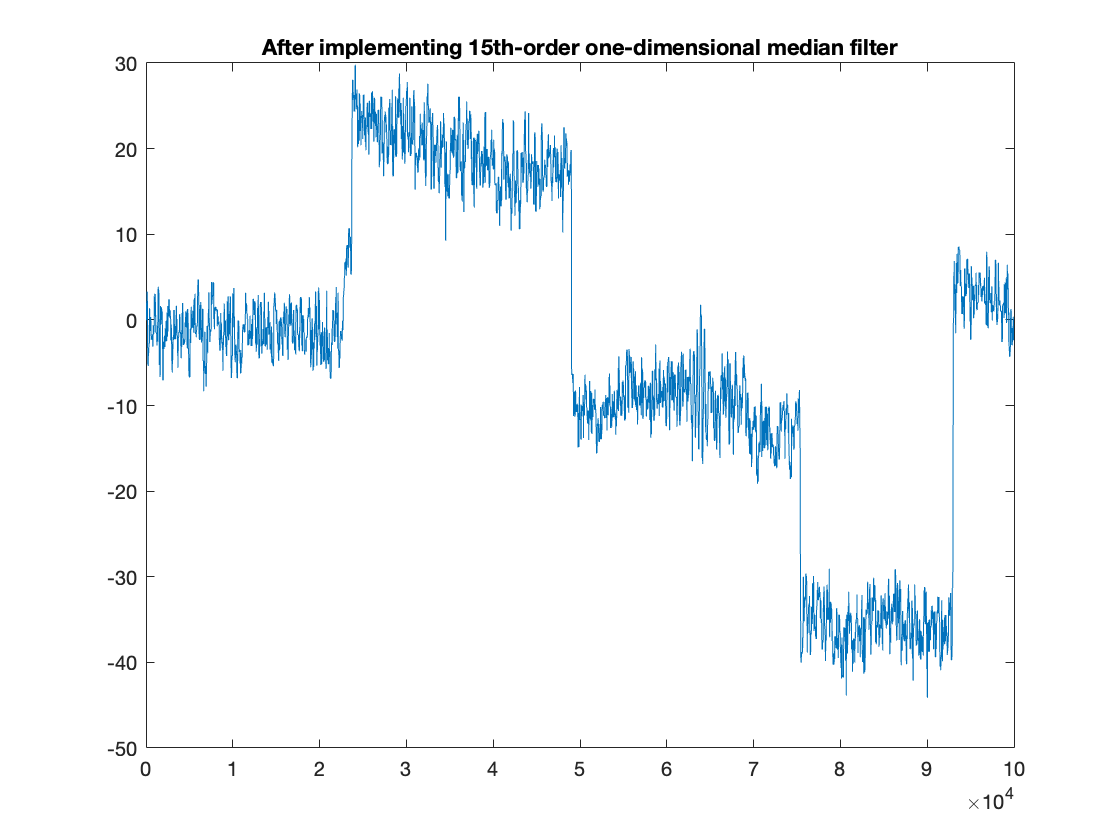


plot(data_15_order(1).time, data_15_order(1).x)
title('After implementing 15th-order one-dimensional median filter');

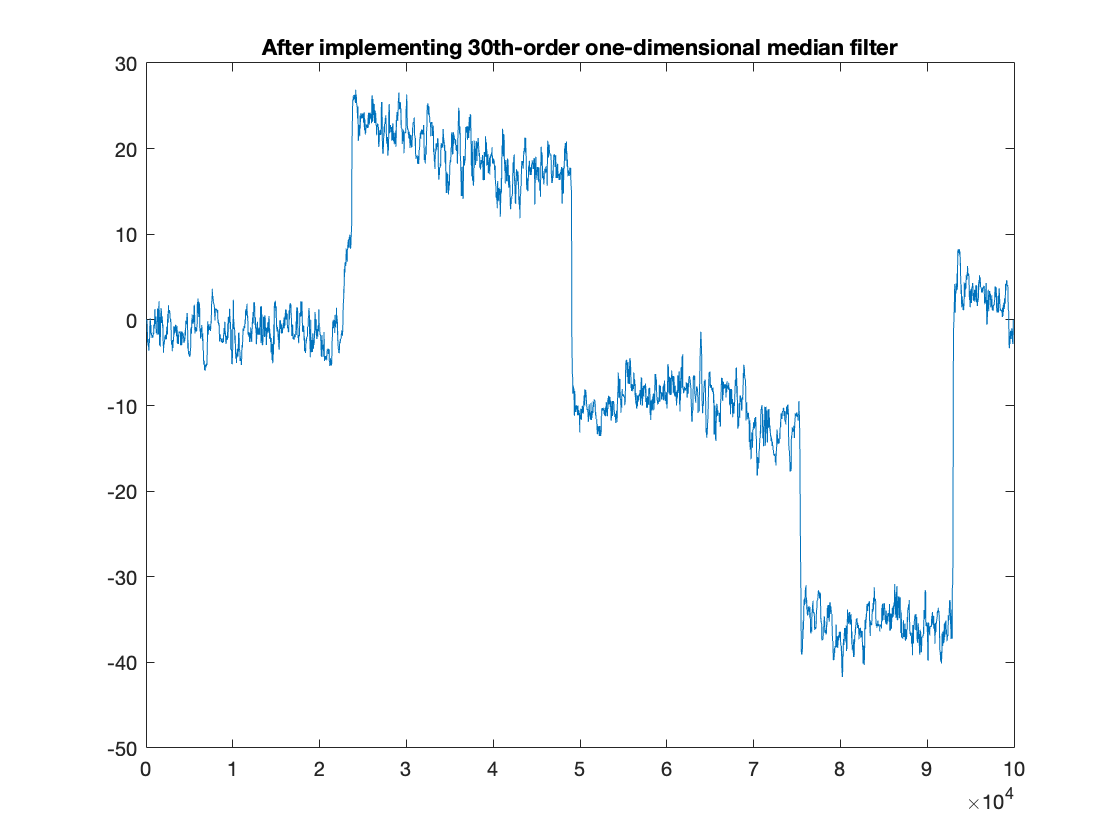


plot(data_30_order(1).time, data_30_order(1).x)
title('After implementing 30th-order one-dimensional median filter');

**Discussion: **

We have done three experiments that are 3rd-order one-dimensional median filter, 15th-order  and 30th-order one-dimensional median filter. From the result images, we can see that 3rd-order one-dimensional median filter performs not as good as 15th-order and 30th-order one-dimensional median filter. 

The median filter compute the median of input signal, and it helps to remove the random noise. However we cannot let the windows size apply median filter be too small or large. For here, 3rd-order and 30th-order one-dimensional median filter are not perform better than 15th-order. They are not very informative if the windows size is too large, but if the windows size is too small then the effect of remove of random noise is not good as well. 

**Q6. **.** Use the waveletAnalyzer tool to explore how wavelet denosing can be applied to denoise the data records.**

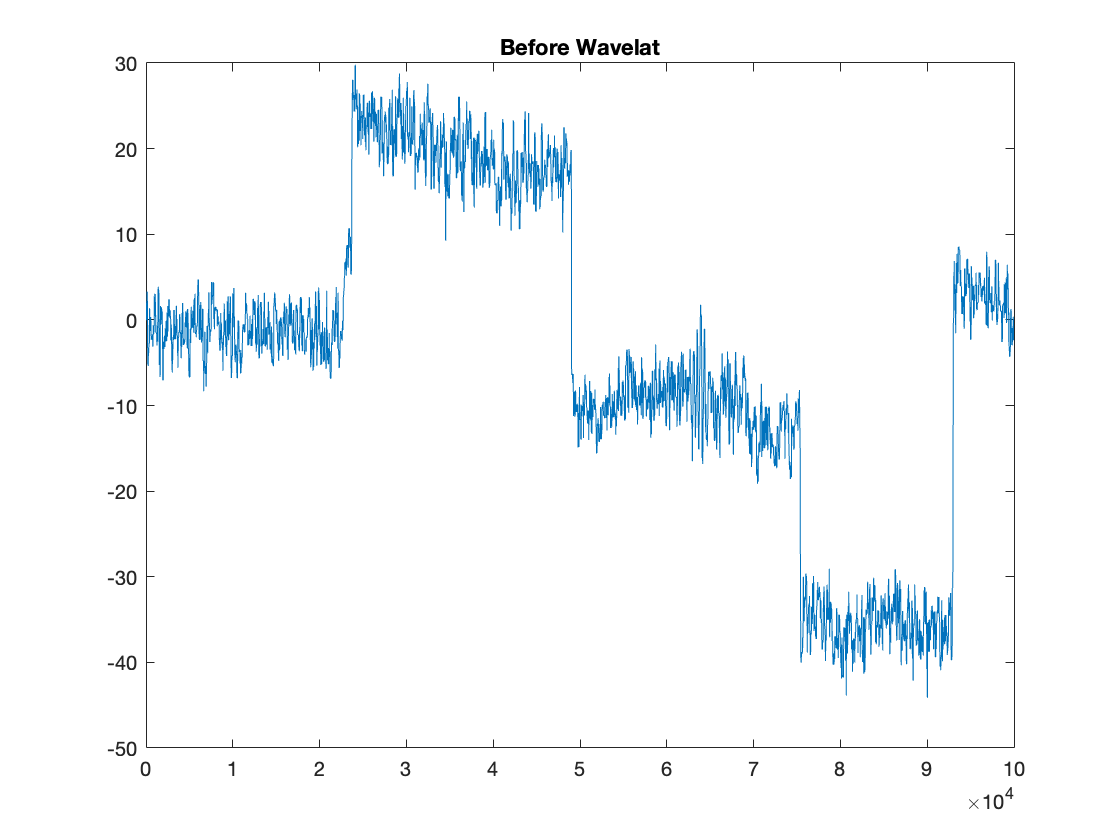

plot(data_15_order(1).time, data_15_order(1).x)
title('Before Wavelat');

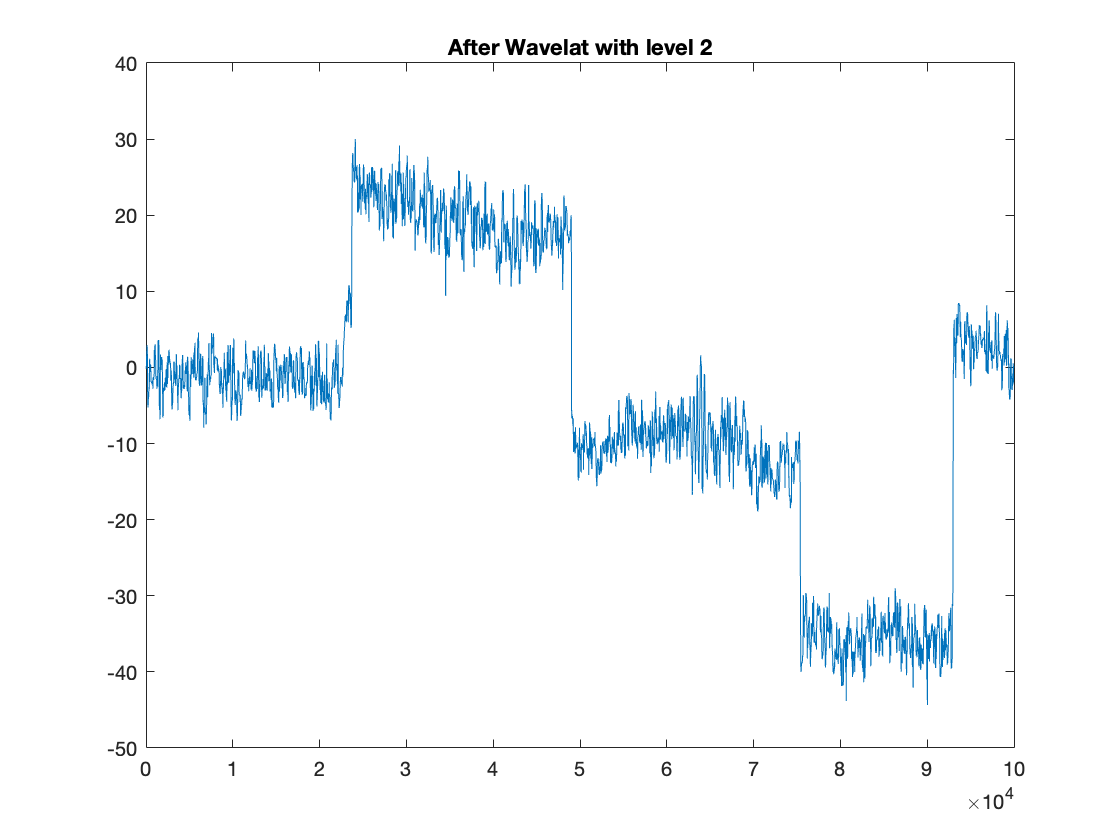


wavelet_level_2 = wdenoise(data_15_order(1).x, 3);
plot(data_15_order(1).time, wavelet_level_2)
title('After Wavelat with level 2');

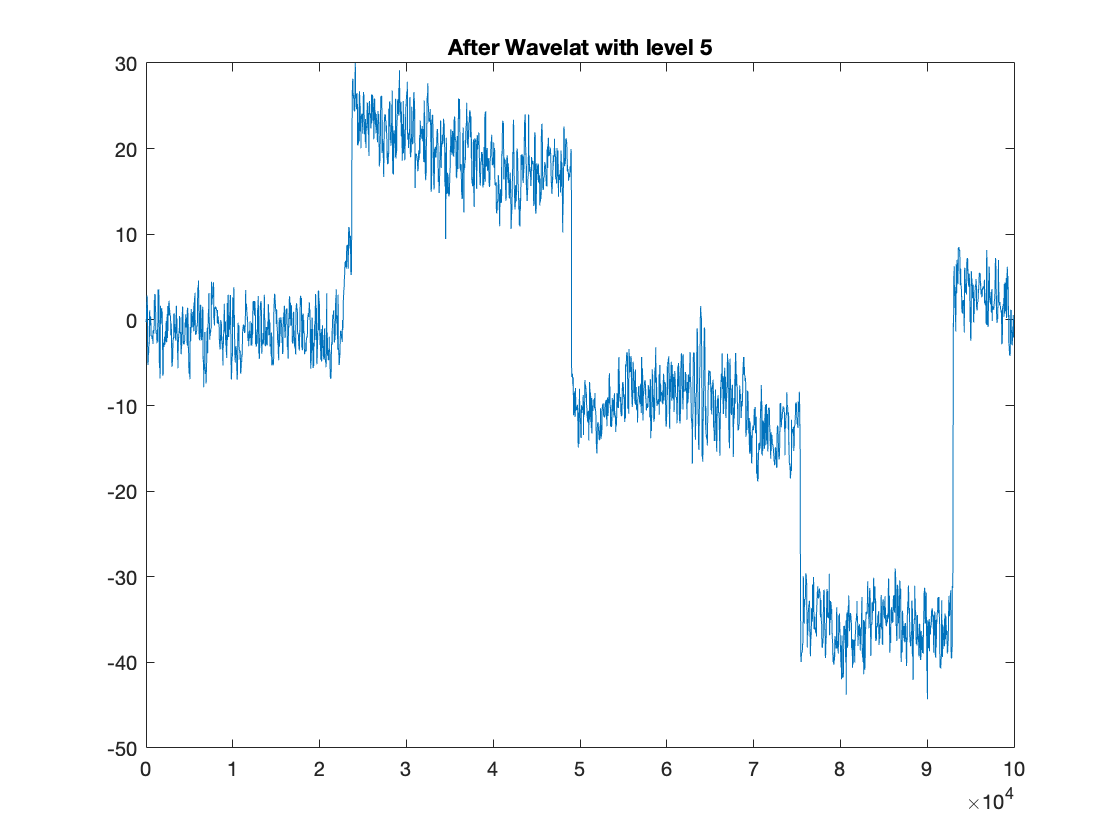


wavelet_level_5 = wdenoise(data_15_order(1).x, 7);
plot(data_15_order(1).time, wavelet_level_5)
title('After Wavelat with level 5');

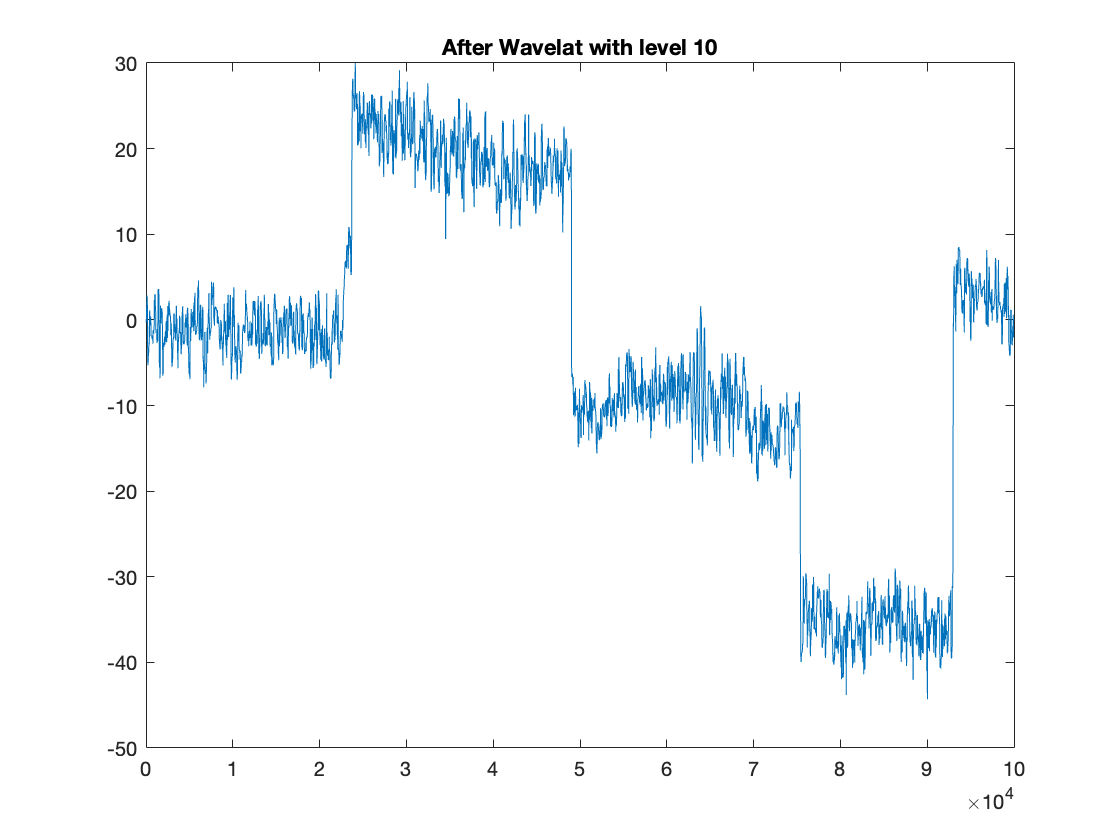


wavelet_level_10 = wdenoise(data_15_order(1).x, 10);
plot(data_15_order(1).time, wavelet_level_10)
title('After Wavelat with level 10');

We have applied   wavelet denosing to the denoise data record 1 from part 5 with levels at 3,7,10. 

**Q7. Implement a full wavelet denosing approach for the full set of 100 data records.**

densor_data = clean_data;

for i = 1:length(clean_data)
    densor_data(i).x = wdenoise(clean_data(i).x, 10);   
    densor_data(i).time = data(i).time;
end

densor_data

densor_data = 1×99 struct array with fields:
    x
    time


**Discuss whether or not (and why) wavelet denoising provides a improved denosing approach over classical noise filtering methods for the given data records *****i.e.*****, If you applied a standard low pass filtering approach to the data what would the results be?**

Wavelet denoising provides a improved denosing approach over classical noise filtering approach methods such as standard low pass filtering approach for the given data records. Low pass filtering do not passes signals's frequency higher than the cutoff frequency [4]. Therefore low pass filtering cannot distingush those high frequency part. While walvelet denoise apply wavelet transforms that result a sparse representation for data records [5].  

**Reference: **

[4] Obeid, Hasan & Khettab, Hakim & Marais, Louise & Hallab, Magid & Laurent, Stéphane & Boutouyrie, Pierre. (2017). Evaluation of arterial stiffness by finger-toe pulse wave velocity: optimization of signal processing and clinical validation. Journal of hypertension. 35. 10.1097/HJH.0000000000001371. 

[5] *wdenoise*. MATLAB & Simulink. (n.d.). https://www.mathworks.com/help/wavelet/ug/wavelet-denoising.html. 

**Q8. Post denoising, develop and apply an appropriate methodology for correcting for the discontinuities that arise within the data records and discuss when such corrections are appropriate and when they are not.**

**Would your developed approach continue to work for real-time (streamed) data? Discuss why or why not and the issues and complexities that real-time (streamed) data introduces.**

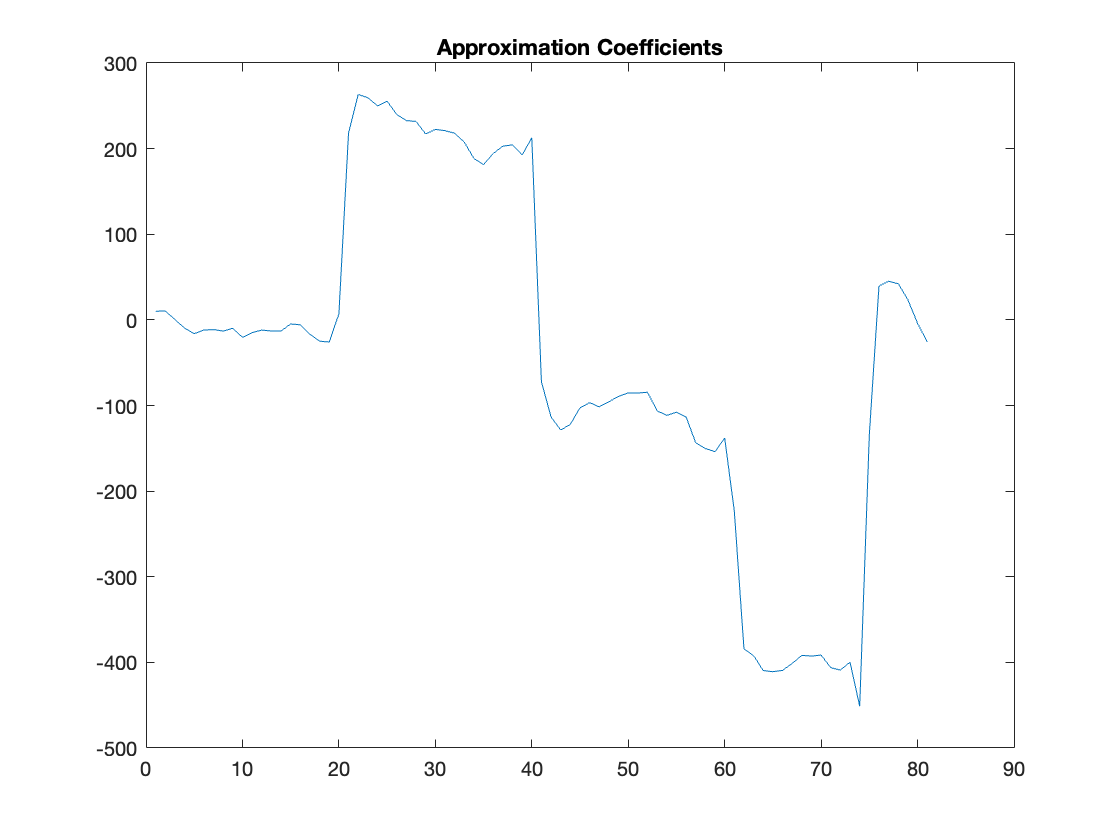

% wavelet decomposition of the 1-D signal x at level 7 ->(round((3+10)/2))
data1 = densor_data(1).x;
[c, l] = wavedec(data1, 7, 'db2');
approx = appcoef(c, l, 'db2');
[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);

figure();
plot(approx)
title('Approximation Coefficients')

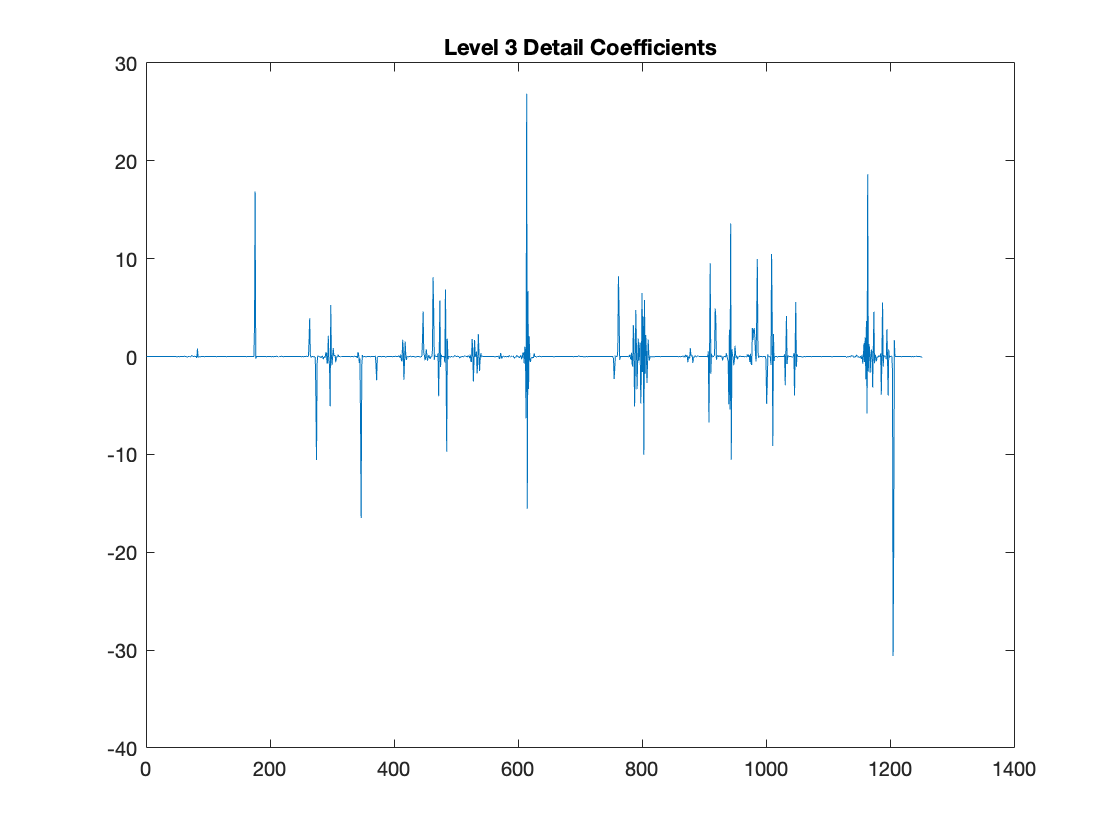

plot(cd3)
title('Level 3 Detail Coefficients')

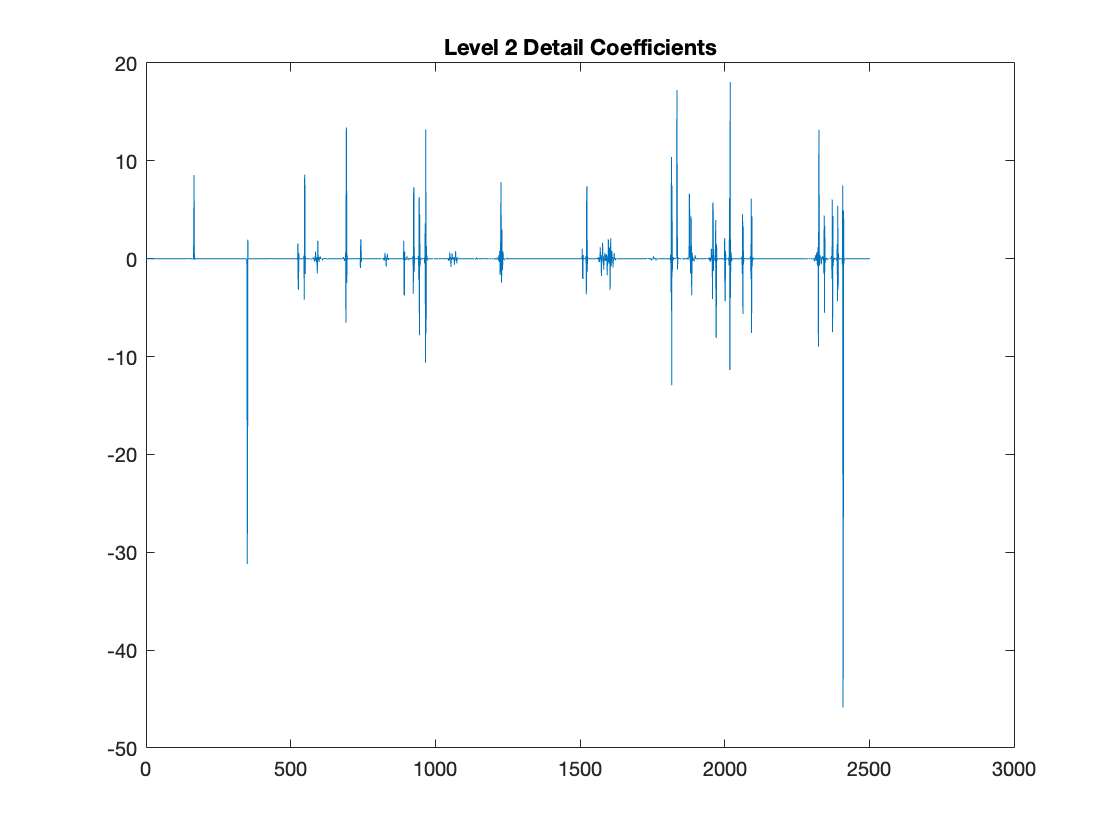

plot(cd2)
title('Level 2 Detail Coefficients')

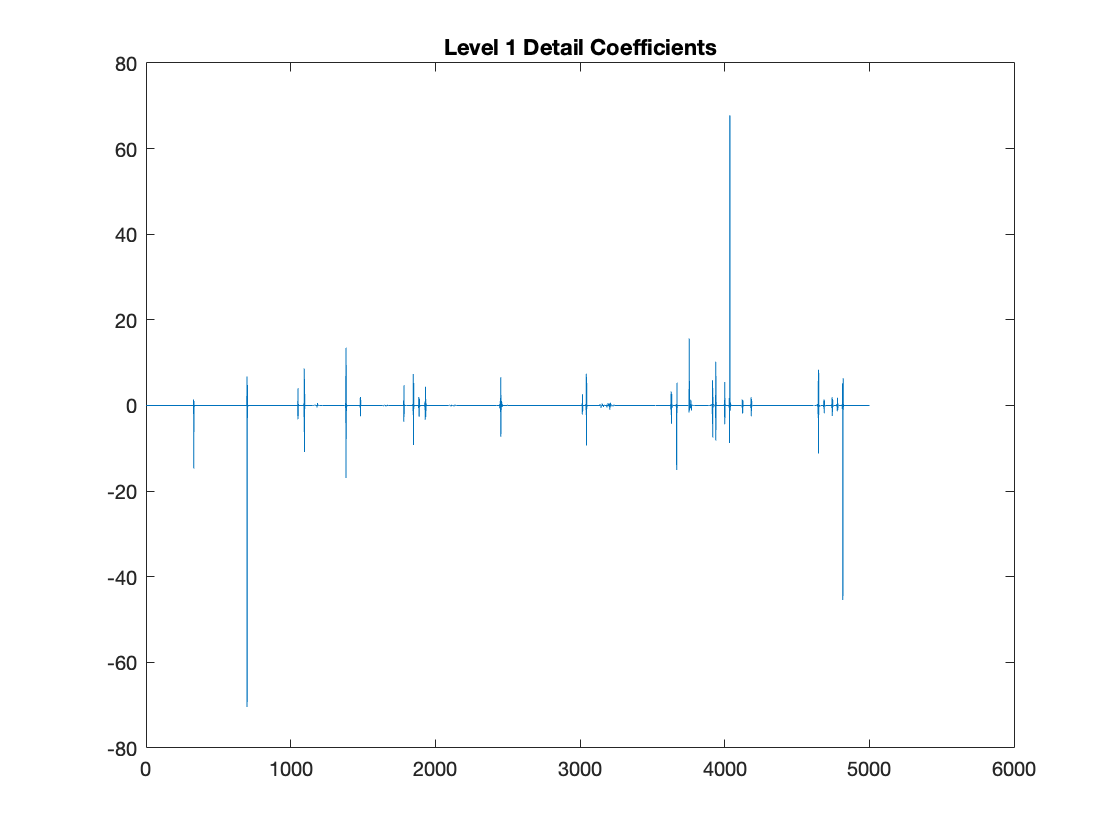

plot(cd1)
title('Level 1 Detail Coefficients')

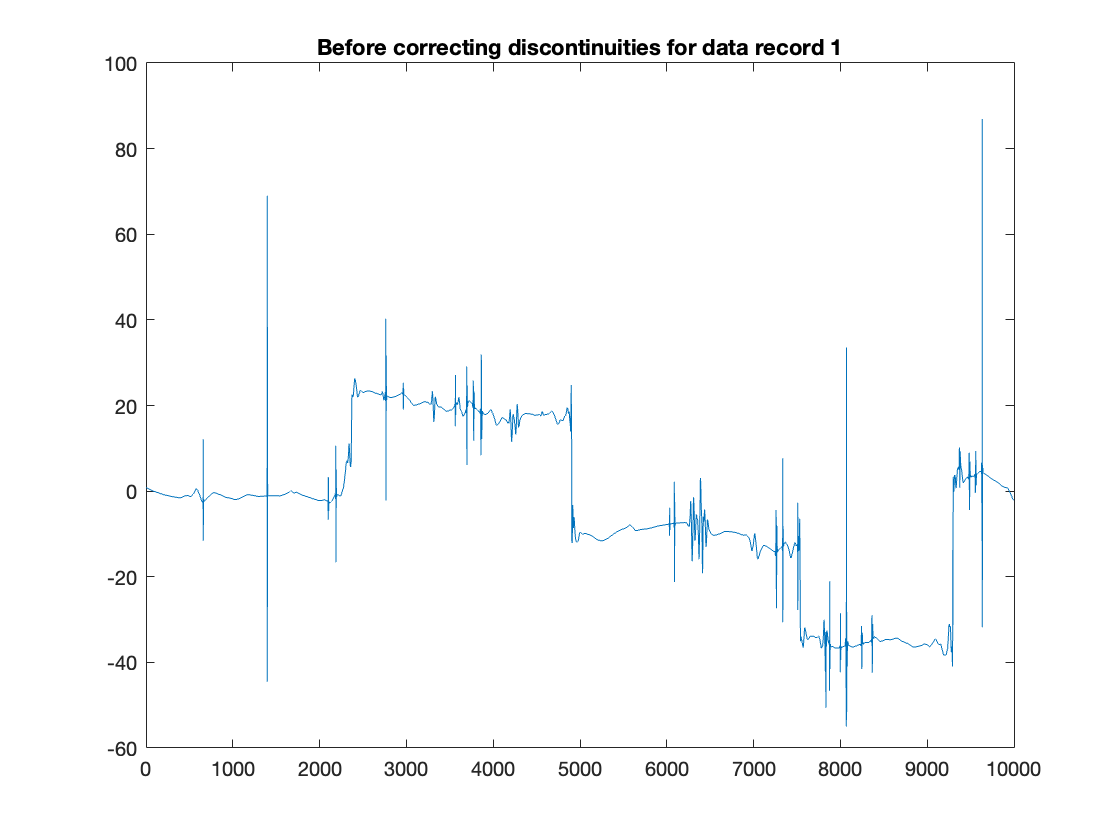


figure();
plot(data1)
title('Before correcting discontinuities for data record 1');

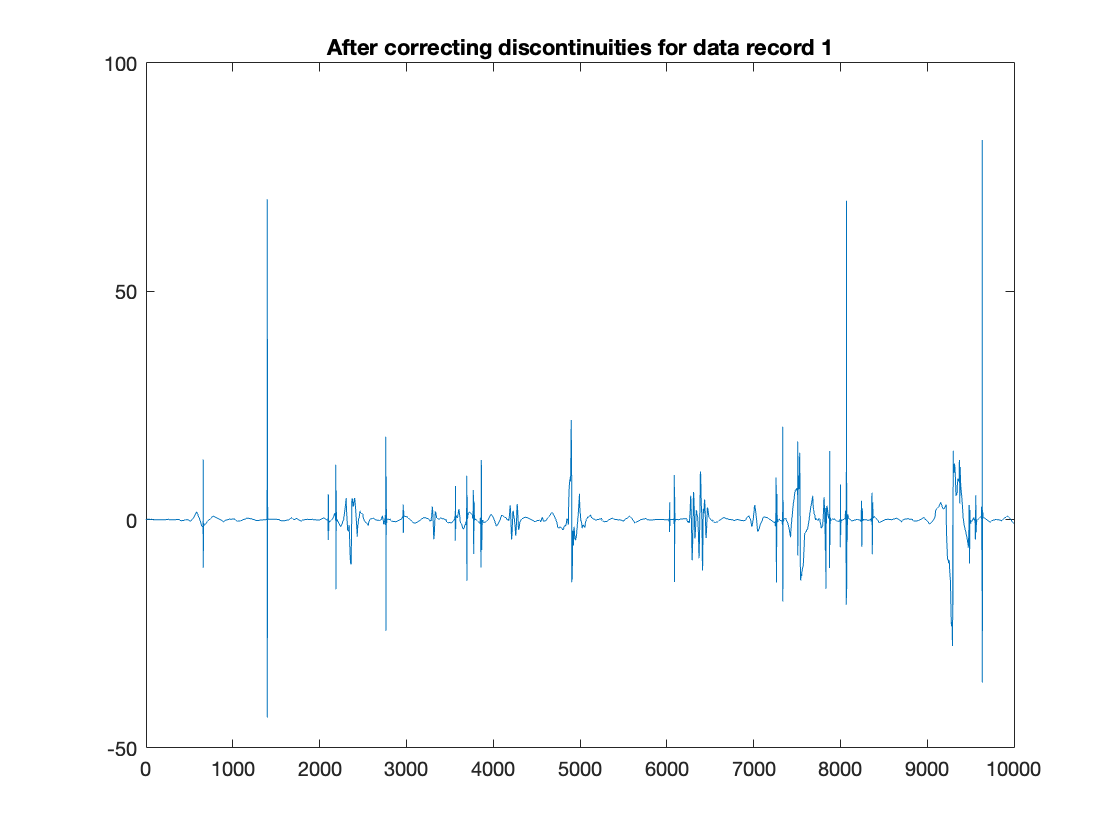



c(length(approx) + 1 : length(c)) = 0; %remove noise
a = data1 - waverec(c, l, 'db2');
plot(a)
title('After correcting discontinuities for data record 1');


continuous_data = clean_data;
for i = 1:length(clean_data)
    [c, l] = wavedec(clean_data(i).x, 7, 'db2');
    approx = appcoef(c, l, 'db2');
    c(length(approx) + 1 : length(c)) = 0;
    a = clean_data(i).x - waverec(c, l, 'db2');
    continuous_data(i).x = a;
    
end

Wavelet denoising does not work for real-time data. When doing walvelet denoise, we first need to wavelet decomposition, then need to find coefficients, and then do walvelet reconstruction. This takes a lot of time, and is not realistic for real-time data. 

**Q9. Apply matching �filtering to locate when the time domain event described by the variable event exists within each of the given data records. **

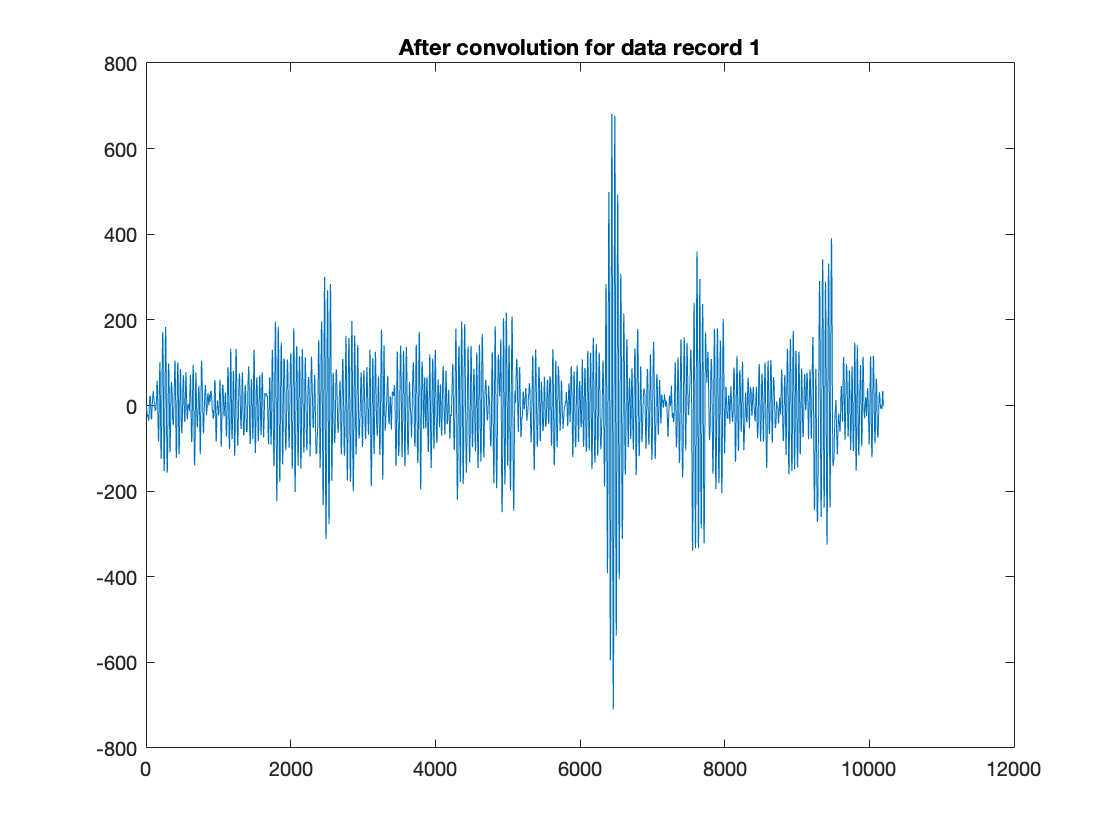

%use convolution
con_data_1 = conv(continuous_data(1).x, event);
plot(con_data_1);
title('After convolution for data record 1');



display('Data records 1 to 25 after convolution'); 

Data records 1 to 25 after convolution


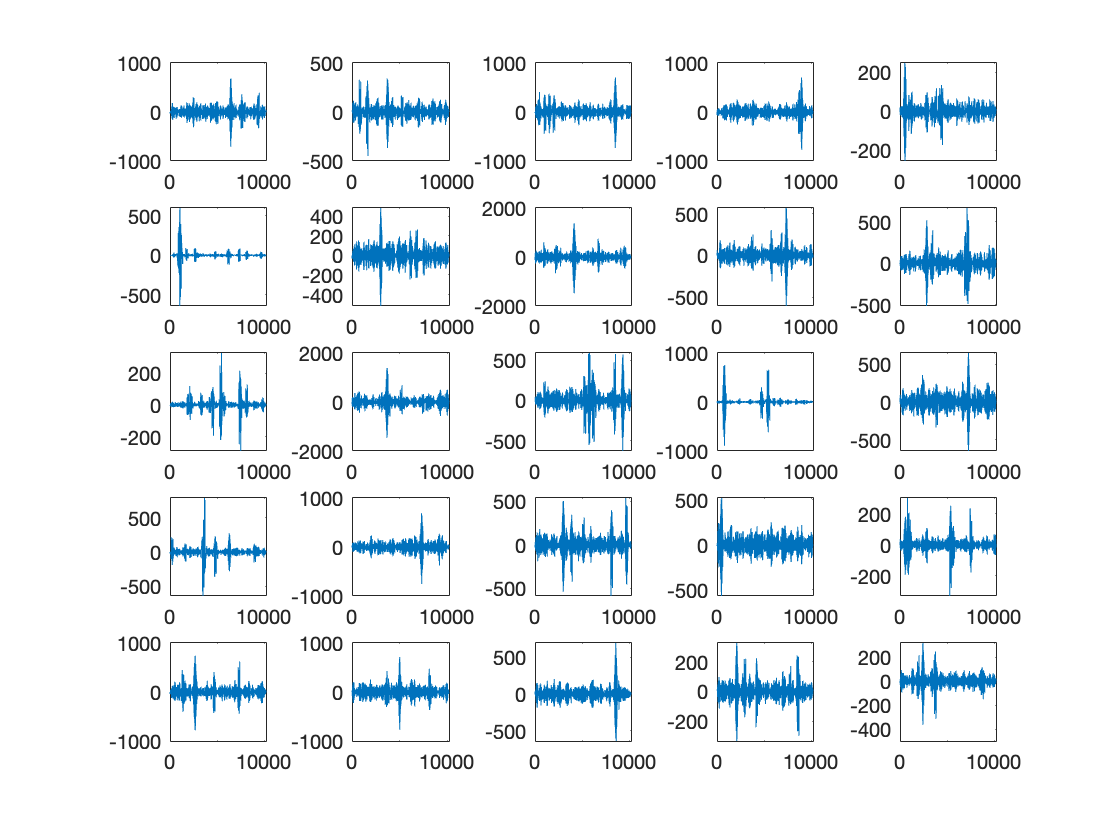

figure();
for i = 1:25   
    subplot(5, 5, i);
    con_data = conv(continuous_data(i).x, event);
    plot(con_data);       
end

hold off;

The convolution represents the overlap area between time domain and event. 

**Discuss the assumptions underlying matched fi�ltering and which situations it will work in and which it will not.**

A matched filter (MF) is commonly defined as the optimal linear filter for maximizing the signal-to-noise ratio (SNR) in the presence of additive stochastic noise [6]. And it can be implemented by find the correlation between time and event. Therefore, if there's no similiarities beteween events and sampled signal, it will not work.

**Reference: **

[6] G. Turin, "An introduction to matched filters," in IRE Transactions on Information Theory, vol. 6, no. 3, pp. 311-329, June 1960, doi: 10.1109/TIT.1960.1057571.